# Exercise 1

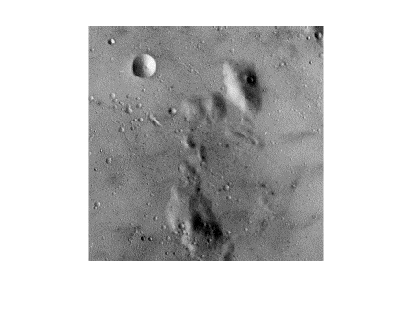


moon = imread("moon.jpg");
figure(1);
tiledlayout(2,3)

imshow(moon);

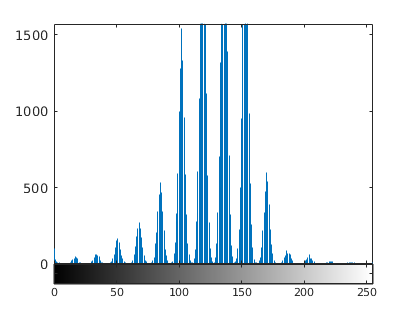



%Transforming into grayscale

gray_moon = rgb2gray(moon);

freq = zeros(256,1);
L = 0:255;

%Cumulative Distribution Function calculation for histogram equalization

[counts,bins]= imhist(gray_moon);

[height, width] = size(gray_moon);

%Find frequency of each intensity and pdf
for i = 1:height
    for j = 1:width
        for k = 1:256
            if gray_moon(i,j) == L(k)
                freq(k) = freq(k) + 1;         
            end
        end
    end
end

pdf = freq / (height*width);
%Find cdf
cdf = cumsum(pdf);
imhist(gray_moon);

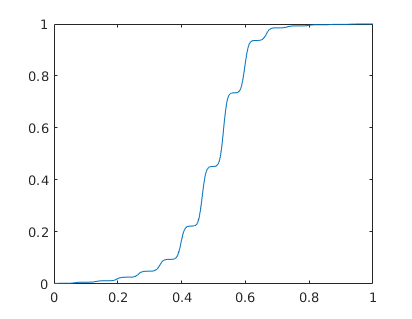

plot((0:255)/255,cdf)

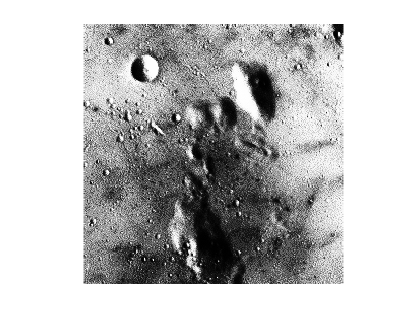

%Histogram Equalization
eq_hist = round(cdf * 255);
equalized_image = zeros(height,width);
%Mapping new gray level
for i = 1:height
    for j = 1:width
        equalized_image(i,j) = eq_hist(gray_moon(i,j)+1);
    end
end% imhist(gray_moon)

%Final image
final_image = uint8(equalized_image);
imshow(final_image)

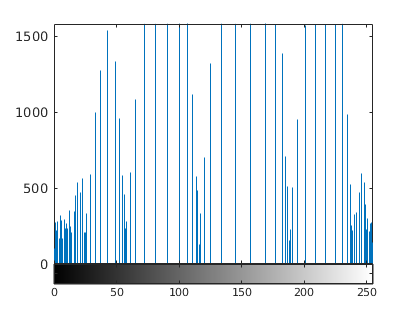


[final_counts, final_bins] = imhist(final_image);
final_cdf = cumsum(final_counts/(height*width));
imhist(final_image)

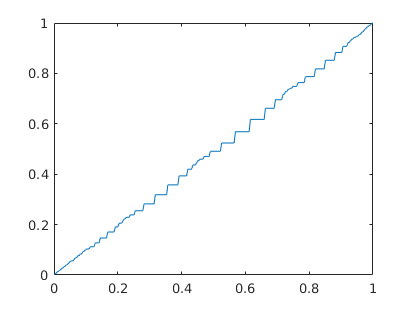

figure
title("Cumulative distribution function of final image")
plot((0:255)/255,final_cdf)

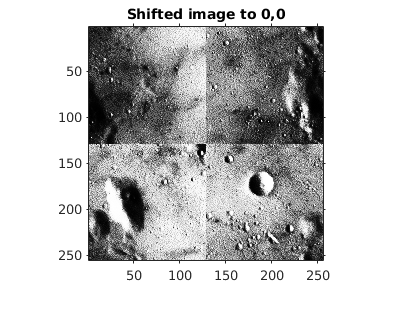

%DFT

%Moving the 0 frequency point at the center with fftshift

shifted_moon = fftshift(final_image);
figure
imshow(shifted_moon);
title("Shifted image to 0,0")
axis on

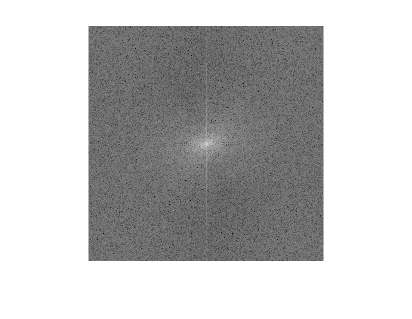


% Calculating the 2D-FFT with 1D-FFT of each row first and then each 
% column
FFT_of_rows = zeros(256,256);
FFT_of_moon = zeros(256,256);

for i = 1:height
    FFT_of_rows(i,:) = fft(shifted_moon(i,:));
end
for i = 1:width
    FFT_of_moon(:,i) = fft(FFT_of_rows(:,i));
end


%Plot the 2D-FFT 
imshow(mat2gray(log(1+abs(fftshift(FFT_of_moon)))))

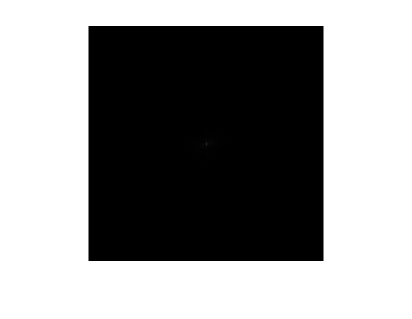

imshow(mat2gray(abs(fftshift(FFT_of_moon))))